clean;
syms Aout Vout Jt Vref Vmax vtot
vtot=(Vref+Vmax);
xcal=Aout*(Aout*Aout/(3*Jt)-Vout)/Jt + ...
    sqrt((  (Vref-Vmax)*vtot*vtot /Jt ));
display((xcal))

$$xcal = \sqrt{-\frac{{\left(\mathrm{Vmax}+\mathrm{Vref}\right)}^{2}\,\left(\mathrm{Vmax}-\mathrm{Vref}\right)}{\mathrm{Jt}}}-\frac{\mathrm{Aout}\,\left(\mathrm{Vout}-\frac{{\mathrm{Aout}}^{2}}{3\,\mathrm{Jt}}\right)}{\mathrm{Jt}}$$

Vmax=Vout-((Aout*Aout)/(2*Jt));
display((Vmax))

$$Vmax = \mathrm{Vout}-\frac{{\mathrm{Aout}}^{2}}{2\,\mathrm{Jt}}$$

syms Xout V1 V4
tempf = (V1 + V4) / Xout;
JtBase = (V1 - V4) * tempf * tempf;
display((JtBase))

$$JtBase = \frac{{\left(V_{1}+V_{4}\right)}^{2}\,\left(V_{1}-V_{4}\right)}{{\mathrm{Xout}}^{2}}$$

clean;
syms r a s v t z
t = (0-a)/r;
z = v + a*t + (1/2)*r*t^2;
display(z);

$$z = v-\frac{a^{2}}{2\,r}$$

z = s + v*t + a*t^2/2 + r*t^3/6;
display(z);

$$z = s+\frac{a^{3}}{3\,r^{2}}-\frac{a\,v}{r}$$

clean;
syms r a s v t z v1 v0
t = solve(0 == a + r*t, t)

$$t = -\frac{a}{r}$$

s = v0*t + a*t^2/2 + r*t^3/6

$$s = \frac{a^{3}}{3\,r^{2}}-\frac{a\,v_{0}}{r}$$

a = solve(v1 == v0 + a*t + r*t^2/2, a)

$$a = \left(\begin{array}{c} \sqrt{2}\,\sqrt{r}\,\sqrt{v_{0}-v_{1}}\\ -\sqrt{2}\,\sqrt{r}\,\sqrt{v_{0}-v_{1}} \end{array}\right)$$

s2 = simplify(subs(s.^2));
display(s2);

$$s2 = \left(\begin{array}{c} \frac{2\,\left(v_{0}-v_{1}\right)\,{\left(v_{0}+2\,v_{1}\right)}^{2}}{9\,r}\\ \frac{2\,\left(v_{0}-v_{1}\right)\,{\left(v_{0}+2\,v_{1}\right)}^{2}}{9\,r} \end{array}\right)$$

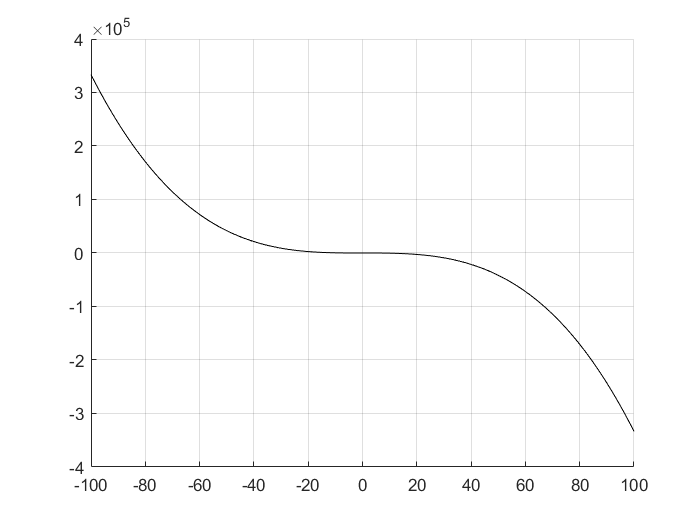

clean;
[a,v] = meshgrid(-100:100, -1000:1000);
r = 1;
s = -a.^3/(3*r^2);
surf(a, v, s); view([0 0]);

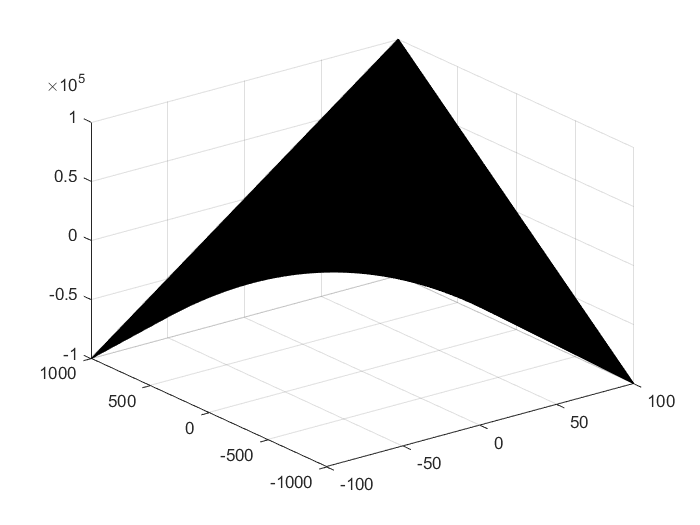

s =  (a.*v)/r;
surf(a, v, s); %view([0 0]);

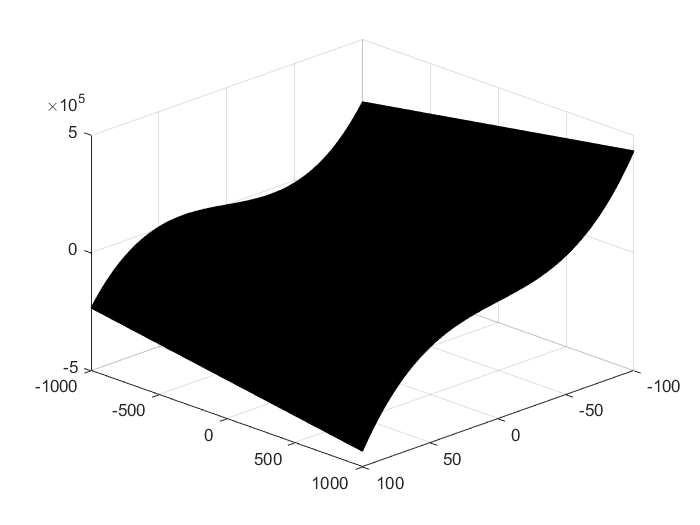

clean;
[a,v] = meshgrid(-100:100, -1000:1000);
r = -1;
s = -a.^3/(3*r^2) + (a.*v)/r;
surf(a, v, s); view([135 30]);

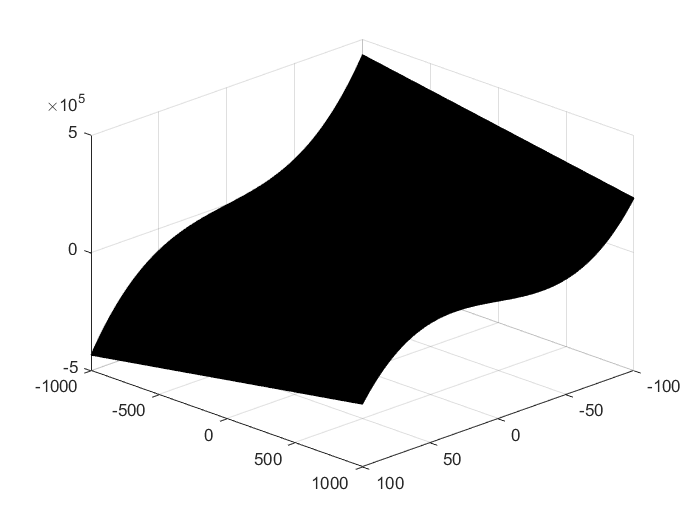

r = 1;
s = -a.^3/(3*r^2) + (a.*v)/r;
surf(a, v, s); view([135 30]);